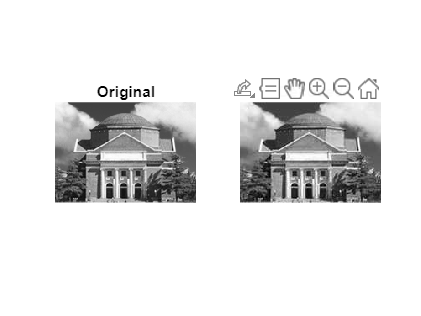

clear
clc

load("jpegcodes.mat");
JpegDecodeImage = JpegDecoder(DCstream,ACstream,h,w);
subplot(1,2,2);
imshow(JpegDecodeImage);
title('Decoded');
load('hall.mat');
subplot(1,2,1);
imshow(hall_gray);
title('Original');

先从主观来看，二者总体差异不明显。但可以在白云或礼堂屋顶和天空过渡处附近看到一些不平滑的噪声，拱门的顶也变得略粗糙。

峰值信噪比 PSNR=10lg(255^2/MSE)

MSE = sum((JpegDecodeImage-hall_gray).^2,'all')/h/w;
PSNR = 10 * log10(255^2/MSE);

得到PSNR=34.8926，大于30dB，数值较大，失真较小